clear
I12(1:6, 1:6) = eye(6);
I12(7:12, 7:12) = -eye(6)

I12 =      1     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0     0     0
     0     0     0     0     0     0    -1     0     0     0     0     0
     0     0     0     0     0     0     0    -1     0     0     0     0
     0     0     0     0     0     0     0     0    -1     0     0     0
     0     0     0     0     0     0     0     0     0    -1     0     0




gamma3 = [  0 0 1 0; 
            0 0 0 1;
            -1 0 0 0 ;
            0 -1 0 0  ]

gamma3 =      0     0     1     0
     0     0     0     1
    -1     0     0     0
     0    -1     0     0


gamma5(3:4, 1:2) = eye(2);
gamma5(1:2, 3:4) = eye(2);

load("conf6_0-4x4-30.mat")
A = full(Problem.A)

A =    0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.1275 - 0.9121i   0.0821 - 0.1027i  -0.0999 - 0.3529i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.9121 + 0.1275i  -0.1027 - 0.0821i  -0.3529 + 0.0999i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.8021 + 0.1485i  -0.2636 + 0.2663i  -0.1113 + 0.4265i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.1485 - 0.8021i  -0.2663 - 0.2636i  -0.4265 - 0.1113i  -0.1843 + 0.6641i  -0.3652 - 0.4038i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.00

kc = 0.16453;
k = 0.95 * kc;

rng(0);
b = rand(size(A,1),1);
n = size(A, 1);
m = n/12

m = 256

G5 = zeros(size(A));

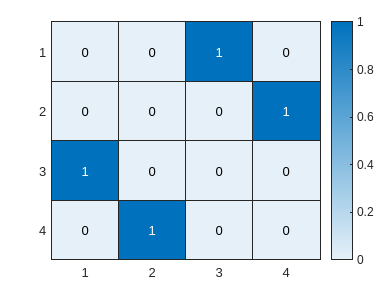

c = 1;
if c == 1
    for i = 1:4:n
        G5(i:i+3, i:i+3) = gamma5;
    end
elseif c == 2
    for i = 1:4:n
        G5(i:i+3, i:i+3) = - gamma3;
    end
else
    for i = 1:12:n
        G5(i:i+11, i:i+11) = I12;
    end
end

heatmap(gamma5)

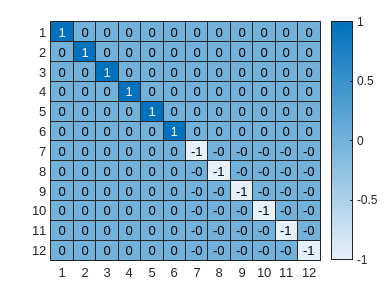

heatmap(I12)

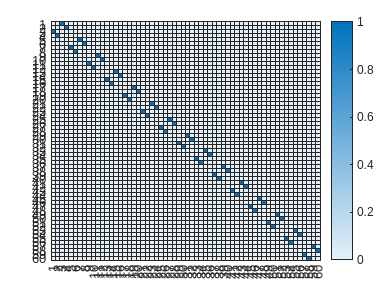

heatmap(G5(1:60, 1:60))

Dgmres = eye(size(A)) -  k * A;
Dminres = G5* (eye(size(A)) + k *A);

[~, fgmres, ~, igmres, resvecgmres] = gmres(Dgmres, b, 250, 1e-8, 2)

fgmres = 0

igmres =      1   205


resvecgmres =    32.0767
   20.1213
   14.6092
   11.7995
   10.0178
    8.7850
    7.8857
    7.2009
    6.5911
    6.0818


resvecgmres = resvecgmres/resvecgmres(1);
[~, fminres, ~, iminres, resvecminres] = minres(Dminres, b, 1e-8, 500)

fminres = 1

iminres = 500

resvecminres =    32.0767
   32.0662
   20.3298
   20.3167
   15.8617
   15.8515
   13.6584
   13.6523
   12.3236
   12.3196


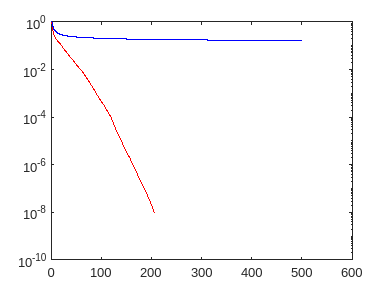

resvecminres = resvecminres/resvecminres(1);              
semilogy(resvecgmres, "r")
hold on;
semilogy(resvecminres, "b")
hold off;